i=randi(300)

i = 212

I = imread(testDataTbl.imageFilename{i});
[bboxes,scores,labels] = detect(detector,I)

bboxes =    169    19    18    41
    53    48    22    33
   138    36    27    43


scores = 3×1 single column vector
    0.9745
    0.9968
    0.9882


labels = 3×1 categorical array
     Batuhan 
     Omer 
     Muhammed 


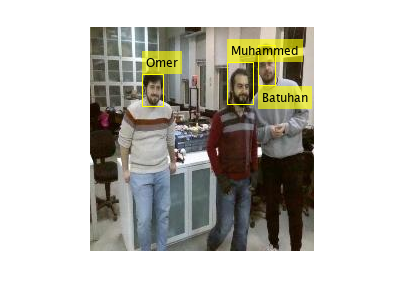

%disp(bboxes,scoes)
detectedI = insertObjectAnnotation(I,'Rectangle',bboxes,cellstr(labels));
figure(gcf);
imshow(detectedI)